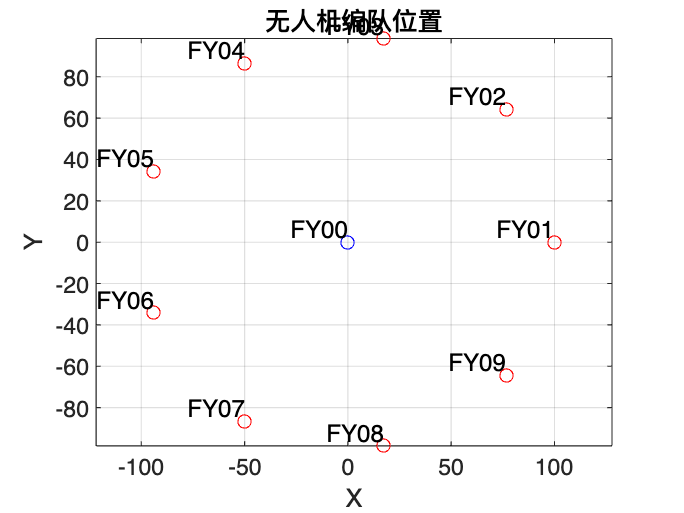

R = 100; % 圆形编队的半径
angles = linspace(0, 2*pi, 10); % 生成10个点的角度，包括起点和终点
angles = angles(1:end-1); % 移除终点，以避免与起点重合

% 计算无人机在圆周上的位置
x = R * cos(angles);
y = R * sin(angles);

% 绘制无人机的位置
figure;
plot(x, y, 'ro'); % 圆周上的无人机
hold on;
plot(0, 0, 'bo'); % 圆心的无人机
axis equal;
grid on;
xlabel('X');
ylabel('Y');
title('无人机编队位置');

% 标记无人机
text(x, y, {'FY01', 'FY02', 'FY03', 'FY04', 'FY05', 'FY06', 'FY07', 'FY08', 'FY09'}, 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
text(0, 0, 'FY00', 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');